## For $\rho_0\propto I_x$

clc;clear

S=load('Sx\LargeNSx');S=S.Expression1

S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9999    0.9998    0.9998    0.9998    0.9997    0.9997    0.9996    0.9996    0.9995    0.9995    0.9994    0.9994    0.9993    0.9992    0.9992    0.9991    0.9990    0.9990    0.9989    0.9988    0.9987    0.9986    0.9985    0.9984    0.9983    0.9982    0.9981    0.9980    0.9979    0.9978    0.9977    0.9976    0.9974    0.9973    0.9972    0.9971    0.9969    0.9968    0.9967    0.9965    0

quench_time_seq=load('Sx\LargeNTime.mat','Expression1');quench_time_seq=quench_time_seq.Expression1;quench_time_seq=transpose(quench_time_seq)

quench_time_seq =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900



end_point_seq=[500:50:1000];
omega=zeros(length(end_point_seq),13);
lambda=zeros(length(end_point_seq),13);
cc=zeros(length(end_point_seq),13);
dd=zeros(length(end_point_seq),13);
omega_upper_bound=zeros(length(end_point_seq),13);
omega_lower_bound=zeros(length(end_point_seq),13);
lambda_upper_bound=zeros(length(end_point_seq),13);
lambda_lower_bound=zeros(length(end_point_seq),13);
contour_success=zeros(length(end_point_seq),13);
resnorm_all=zeros(length(end_point_seq),13);


predicted = @(aa,x) aa(3)*cos(2*pi*aa(1)*x+aa(4)).*exp(-2*pi*aa(2)*x);
% predicted = @(aa,x) aa(3)*cos(2*pi*aa(1)*x+0.5).*exp(-2*pi*aa(2)*x);
% quench_time_seq=(24*5*1e-3)*(0:40); %in ms

for jj=10:length(end_point_seq)
    for ii=3:3
        fprintf('Step ii:%d, jj:%d\n', ii, jj);
% for jj=1:5:27
%     for ii=6
        x=quench_time_seq(1:end_point_seq(jj));
        y=S(ii,1:end_point_seq(jj));
        options = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt');
        grid=1000;
        if ii==1
        grid=1000;
        omega_near=linspace(-10*1e-3,10*1e-3,grid);
        lambda_near=linspace(-5*1e-3,5*1e-3,grid);
        a0 = [0.001;0.003;1;-0.];
        [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
        end
        if ii==2
            grid=1000;
            a0 = [0.001;0.003;1;-0];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-4,aa(1)+7e-4,grid);
            lambda_near=linspace(aa(2)-7e-4,aa(2)+7e-4,grid);
        end
        if ii==3
            grid=1000;
            a0 = [0.001;0.03;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
%             omega_near=linspace(aa(1)-1e-3,aa(1)+1e-3,grid);
%             lambda_near=linspace(aa(2)-1e-3,aa(2)+1e-3,grid);
            if jj==1 || ((jj>=6) && (jj<=9))  
                omega_near=linspace(aa(1)-1e-3,aa(1)+1e-3,grid);
                lambda_near=linspace(aa(2)-1e-3,aa(2)+1e-3,grid);
            elseif jj >= 10
                omega_near=linspace(aa(1)-8e-3,aa(1)+8e-3,grid);
                lambda_near=linspace(aa(2)-8e-3,aa(2)+8e-3,grid);
            else
                omega_near=linspace(aa(1)-20e-3,aa(1)+20e-3,grid);
                lambda_near=linspace(aa(2)-20e-3,aa(2)+20e-3,grid);
            end
        end
        if ii==4
            grid=1000;
            a0 = [0.001;0.03;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-3,aa(1)+7e-3,grid);
            lambda_near=linspace(aa(2)-7e-3,aa(2)+7e-3,grid);
        end
        if ii==5
            grid=1000;
            a0 = [0.001;0.1;1;-0.];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            omega_near=linspace(aa(1)-7e-3,aa(1)+7e-3,grid);
            lambda_near=linspace(aa(2)-7e-3,aa(2)+7e-3,grid);
        end
        if ii>=6 && ii<=11
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.01,aa(1)+0.01,grid);
            lambda_near=linspace(aa(2)-0.01,aa(2)+0.01,grid);
        end
        if ii==12
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.05,aa(1)+0.05,grid);
            lambda_near=linspace(aa(2)-0.05,aa(2)+0.05,grid);
        end
        if ii==13
            a0 = [0.2;0.3;1;-0.3];
            [aa,resnorm,residual] =lsqcurvefit(predicted,a0,x,y,[0 -Inf -Inf -3],[Inf Inf 1.5 Inf],options);
            grid=1000;
            omega_near=linspace(aa(1)-0.05,aa(1)+0.05,grid);
            lambda_near=linspace(aa(2)-0.05,aa(2)+0.05,grid);
        end

        omega(jj,ii)=aa(1); %in kHz
        lambda(jj,ii)=aa(2); %in kHz
        cc(jj,ii)=aa(3);
        dd(jj,ii)=aa(4);

        resnorm_all(jj,ii)=resnorm;

%         figure()
%         y_fit=aa(3)*cos(2*pi*aa(1)*x+aa(4)).*exp(-2*pi*aa(2)*x);
%         % y_fit=aa(3)*cos(2*pi*aa(1)*x+0.5).*exp(-2*pi*aa(2)*x);
%         plot(x,y,'o',x,y_fit,'-')

### 画出resnorm的等高线图

        ydata=omega_near;
        xdata=lambda_near;
        resnorm_near=zeros(length(xdata),length(ydata));
        for i=1:length(ydata)
            for j=1:length(xdata)
                y_near=aa(3)*cos(2*pi*omega_near(i)*x+aa(4)).*exp(-2*pi*lambda_near(j)*x);
                % y_near=aa(3)*cos(2*pi*omega_near(i)*x+0.5).*exp(-2*pi*lambda_near(j)*x);
                resnorm_near(i,j)=sum((y_near-y).^2);
            end
        end

        % figure()
        % [xxdata,yydata]=meshgrid(xdata,ydata);
        % mesh(xxdata,yydata,(resnorm_near-resnorm)/resnorm)
        % ylabel('\omega')
        % xlabel("\lambda")
        % zlabel('sum of square of residues')

        p=0.95;
        nu1=2; %number of free parameters
        nu2=length(y)-length(aa);
        delta_resnorm=finv(p,nu1,nu2)*nu1/nu2;

%        
        M=contourc(xdata,ydata,(resnorm_near-resnorm)/resnorm,[delta_resnorm,delta_resnorm]); %not show contour

%         figure()
%         [M]=contour(xdata,ydata,(resnorm_near-resnorm)/resnorm,[delta_resnorm,delta_resnorm]); %show contour
%         ylabel('\omega')
%         xlabel("\lambda")


        if ii == 1
            omega_upper_bound(jj,ii)=0.0;
            omega_lower_bound(jj,ii)=0.0;
            lambda_upper_bound(jj,ii)=0.0;
            lambda_lower_bound(jj,ii)=0.0;
            
            contour_success(jj,ii)=1;
        else
            
            MM=M(2,:);
            [contour_index]=find(M(1,:)==delta_resnorm);
            [~,right_contour]=min(abs(MM(contour_index+1)-aa(1))); %pick the right contour
            right_index=contour_index(right_contour);
            num_points=MM(right_index);
            contour_success(jj,ii)=(num_points==length(M(2,right_index+1:right_index+num_points)));
            if contour_success == 0
                fprintf('Fail at: ii:%d, jj:%d\n', ii, jj);
            end
            omega_upper_bound(jj,ii)=max(M(2,right_index+1:right_index+num_points),[],2);
            omega_lower_bound(jj,ii)=min(M(2,right_index+1:right_index+num_points),[],2);
            lambda_upper_bound(jj,ii)=max(M(1,right_index+1:right_index+num_points),[],2);
            lambda_lower_bound(jj,ii)=min(M(1,right_index+1:right_index+num_points),[],2);
        end
    end
end

Step ii:3, jj:10



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


Step ii:3, jj:11



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


clear resnorm_near

[j,i]=find(contour_success==0) %check the number of points on the contour

j =     10
    11


i =      3
     3


figure()
xi=-0.4:0.05:0.2;
lower_bar=omega-omega_lower_bound;
upper_bar=omega_upper_bound-omega;

% errorbar(xi,transpose(omega),transpose(lower_bar),transpose(upper_bar),'-o')
errorbar(xi,mean(omega),max(lower_bar),max(upper_bar),'-o')
fprintf('%f,',mean(omega));fprintf('\n');

0.000000,0.001762,0.000000,0.000000,0.017813,0.147977,0.248224,0.322731,0.380253,0.419501,0.449335,0.474026,0.493874,


fprintf('%f,',max(lower_bar));fprintf('\n');

0.000001,0.000700,0.001133,0.006655,0.007000,0.003163,0.002696,0.003493,0.004361,0.004474,0.004990,0.005126,0.005009,


fprintf('%f,',max(upper_bar));fprintf('\n');

0.000000,0.000455,0.001029,0.006655,0.007000,0.003112,0.002674,0.003455,0.004297,0.004417,0.004936,0.005082,0.004969,


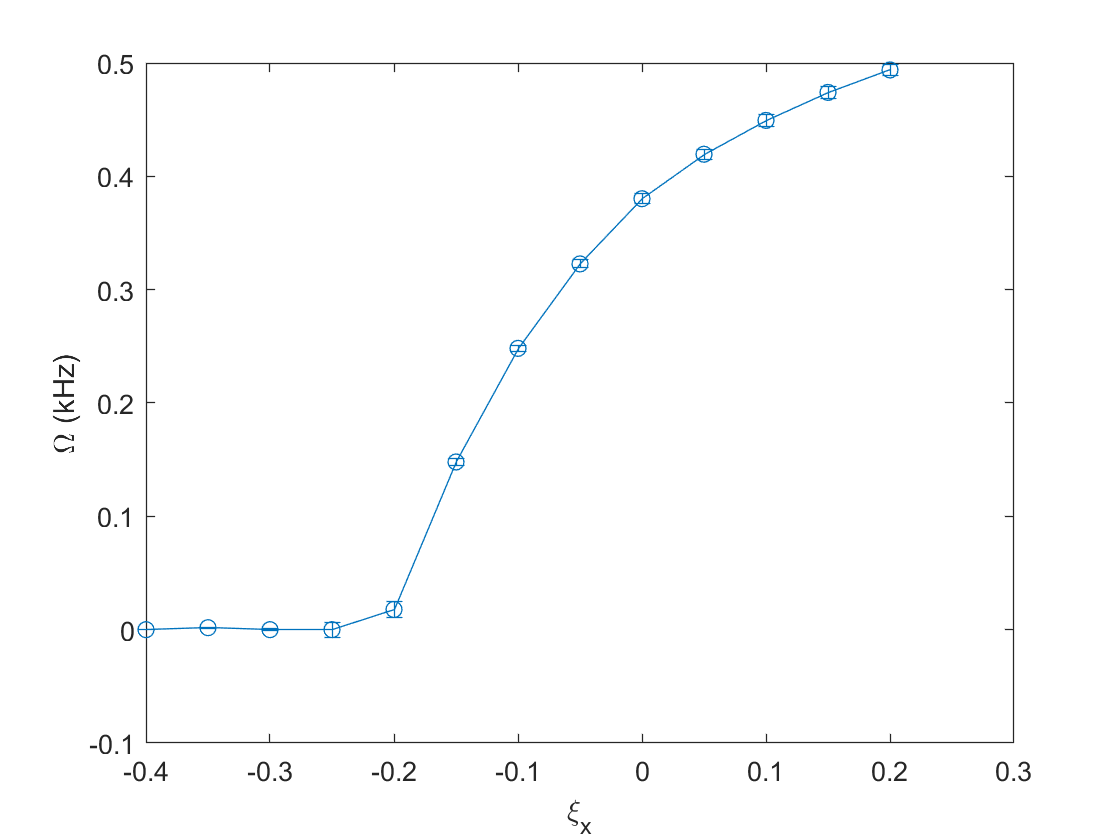

% errorbar(xi,omega,lower_bar,upper_bar)
xlabel('\xi_x')
ylabel('\Omega (kHz)')

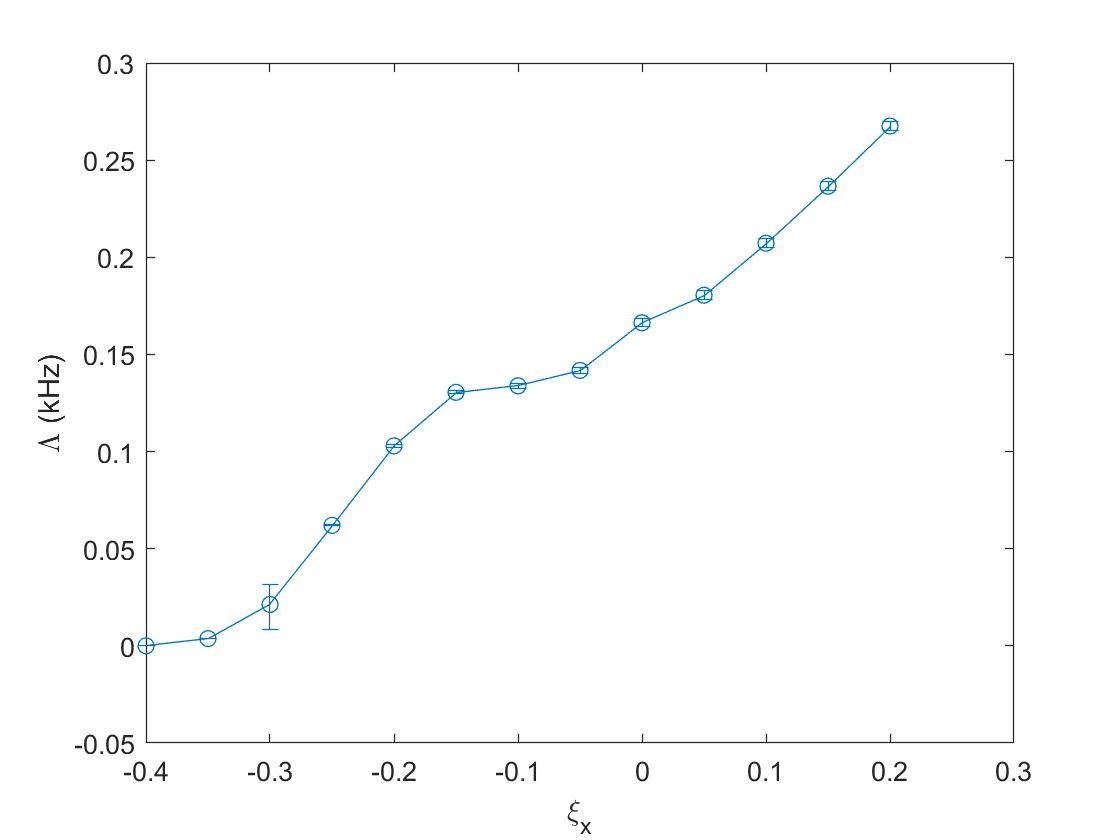

% legend('15 fitting points','41 fitting points','box','off')

figure()
lower_bar=lambda-lambda_lower_bound;
upper_bar=lambda_upper_bound-lambda;
errorbar(xi,mean(lambda),max(lower_bar),max(upper_bar),'-o')
% errorbar(xi,lambda,lower_bar,upper_bar,'-o')
% errorbar(xi,lambda,lower_bar,upper_bar)
xlabel('\xi_x')
ylabel('\Lambda (kHz)')

fprintf('%f,',mean(lambda));fprintf('\n');

0.000000,0.003736,0.021317,0.062038,0.102926,0.130513,0.133844,0.141768,0.166302,0.180478,0.207218,0.236584,0.267538,


fprintf('%f,',max(lower_bar));fprintf('\n');

0.000000,0.000036,0.012994,0.000236,0.000574,0.000675,0.001205,0.001564,0.002024,0.002141,0.002300,0.002419,0.002503,


fprintf('%f,',max(upper_bar));fprintf('\n');

0.000000,0.000036,0.010380,0.000237,0.000577,0.000679,0.001220,0.001591,0.002063,0.002179,0.002339,0.002452,0.002539,


% legend('15 fitting points','41 fitting points','box','off')


figure()
xi=-0.4:0.05:0.2;
plot(xi,omega,'-o')
find(omega(:,6)<0.01)


ans =

  空的 0×1 double 列向量



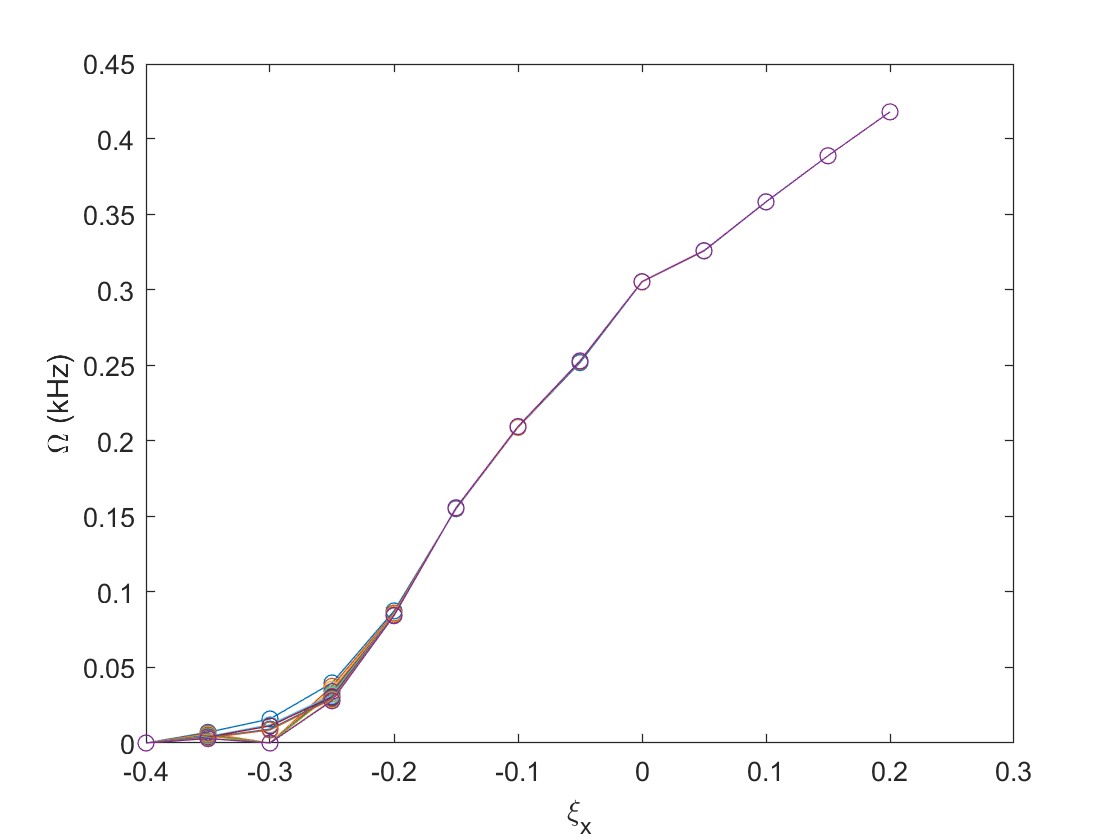

xlabel('\xi_x')
ylabel('\Omega (kHz)')

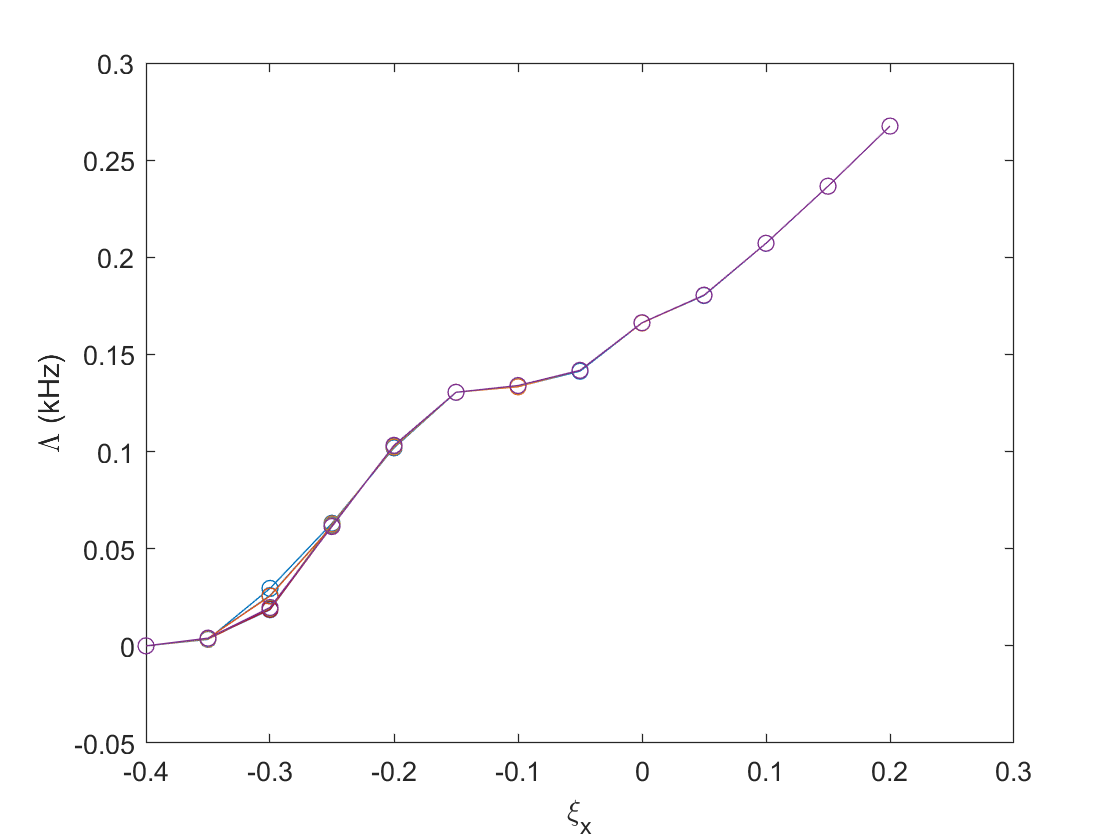

figure()
plot(xi,lambda,'-o')
xlabel('\xi_x')
ylabel('\Lambda (kHz)')

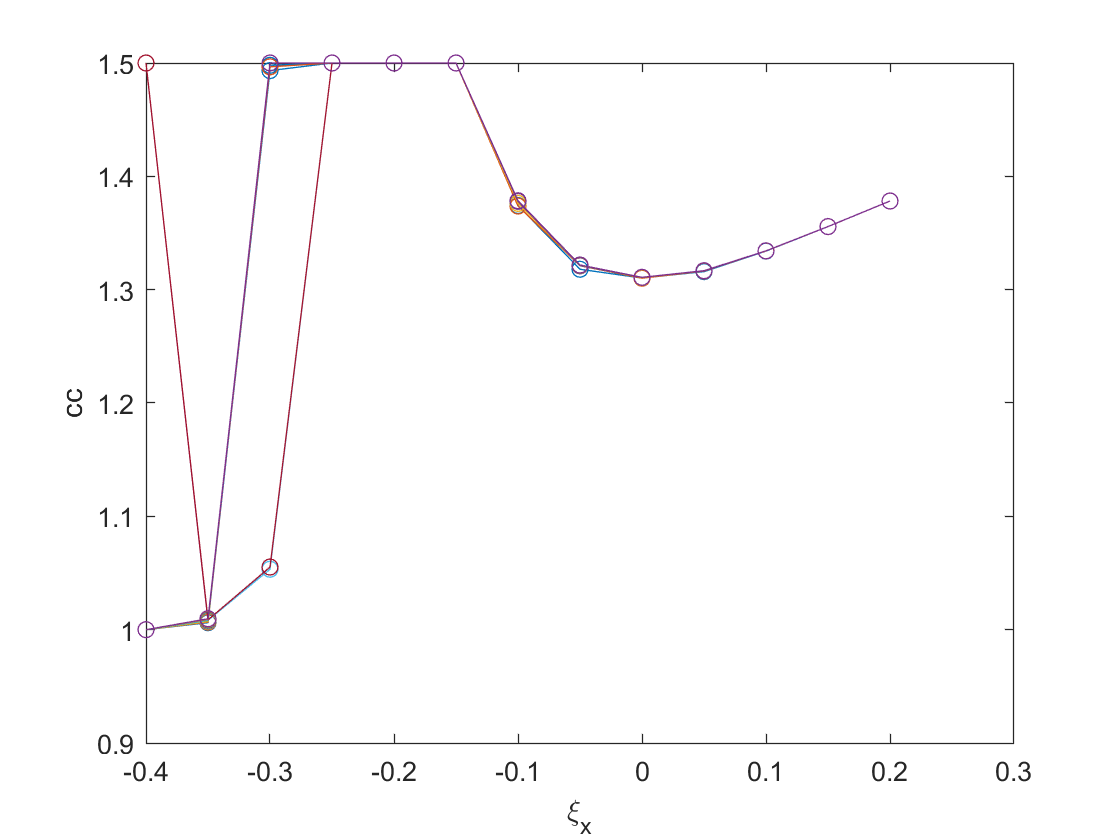

figure()
plot(xi,cc,'-o')
xlabel('\xi_x')
ylabel('cc')

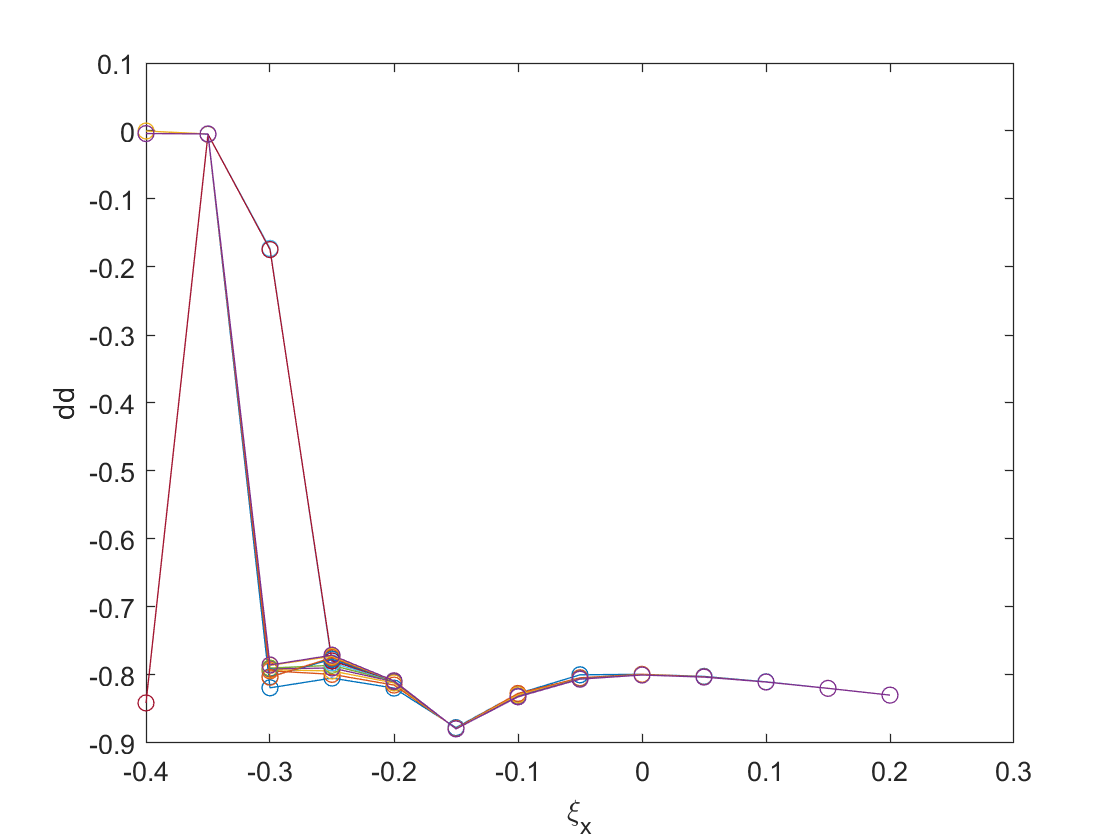

figure()
plot(xi,dd,'-o')
xlabel('\xi_x')
ylabel('dd')

looking into the sum of squares of residues

figure()
plot(end_point_seq, resnorm_all)
xlabel('Number of fitting points')
ylabel('Sum of residue squares')
figure()
plot(end_point_seq, sqrt(resnorm_all./end_point_seq'))
xlabel('Number of fitting points')
ylabel('root of mean squared residues')

 保存变量

save('Sx\LargeN_resnorm_all.mat','resnorm_all')
save('Sx\LargeN_omega.mat','omega')
save('Sx\LargeN_omega_lower_bound.mat','omega_lower_bound')
save('Sx\LargeN_omega_upper_bound.mat','omega_upper_bound')
save('Sx\LargeN_lambda.mat','lambda')
save('Sx\LargeN_lambda_lower_bound.mat','lambda_lower_bound')
save('Sx\LargeN_lambda_upper_bound.mat','lambda_upper_bound')
save('Sx\LargeN_cc.mat','cc')
save('Sx\LargeN_dd.mat','dd')

Load变量

lambda=load('Sx\LargeN_lambda.mat').lambda;
lambda_lower_bound=load('Sx\LargeN_lambda_lower_bound.mat').lambda_lower_bound;
lambda_upper_bound=load('Sx\LargeN_lambda_upper_bound.mat').lambda_upper_bound;